Fit, compare, analyze, and plot Experiment 3 behavioural models

projectDir = '/Users/foxxis/Desktop/HBI/exp3';
cd(projectDir);
addpath(projectDir);

addpath(fullfile(projectDir, 'src'));
addpath(fullfile(projectDir, 'src', 'models'));
addpath(fullfile(projectDir, 'src', 'plotting'));
addpath(fullfile(projectDir, 'src', 'r2_assignment'));

Load Experiment 3 data.

xlsx_file = '/Users/foxxis/Documents/social induction/experiment data/exp3/final_data.xlsx';

raw_tbl = readtable(xlsx_file);
vars = arrayfun(@(i) sprintf('p%d', i), 1:16, 'UniformOutput', false);

Y = table2array(raw_tbl(:, vars));
N = size(Y, 1);

data = cell(N, 1);
for s = 1:N
    data{s} = struct('y', Y(s,:));
end

Prepare fitting output folder. results/fitting is the output location

fitDir = fullfile(projectDir, 'results', 'fitting');
if exist(fitDir, 'dir') ~= 7
    mkdir(fitDir);
end

outputs = struct();

Model fitting and HBI comparison.

validate_cbm_data(data);

cbm_root = '/Users/foxxis/Documents/MATLAB/cbm-master';
addpath(genpath(cbm_root));

assert(exist('cbm_lap', 'file') == 2, ...
    'Cannot find cbm_lap. Check cbm_root in BMI_run_exp3.mlx.');

cd(fitDir);

% The variance v controls the scale of the zero-mean Laplace prior on each
% parameter. A value of 6.25 is suggested by the CBM manual, which is
% large enough to cover a wide range of parameters with no excessive
% penalty. As our model parameters are additionally transformed with exp()
% in the likelihood function, we use log(6.25) ~= 1.8 to avoid overly
% dispersed initial parameter values.
% Robustness checks were also run with alternative v values.
v = 1.8;

% First, we should run cbm_lap, which fits every model to each subject data
% separately (i.e. in a non-hierarchical fashion).
% Mentalizing model: one free parameter (log_ce)
prior_ment = struct('mean', zeros(1,1), 'variance', v);
cbm_lap(data, @mentalizing_model, prior_ment, 'lap_mentalizing.mat');

cbm_lap                                           24-Sep-2026 15:15:18
Number of samples: 96
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


% Level-0 model: two free parameters (log_ce, log_n)
prior_vt = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @vt_model, prior_vt, 'lap_vt.mat');

cbm_lap                                           24-Sep-2026 15:15:20
Number of samples: 96
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level-1 (diversity weighted) model: three free parameters (log_ce, log_n, log_e)
prior_dw = struct('mean', zeros(3,1), 'variance', v);
cbm_lap(data, @dw_model, prior_dw, 'lap_dw.mat');

cbm_lap                                           24-Sep-2026 15:15:26
Number of samples: 96
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level-2 (knowledge weighted) model: two free parameters (log_ce, log_n)
prior_kw = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @kw_model, prior_kw, 'lap_kw.mat');

cbm_lap                                           24-Sep-2026 15:15:38
Number of samples: 96
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Baseline model: zero free parameters (uniform over responses)
prior_base = struct('mean', 0, 'variance', v);
cbm_lap(data, @baseline_model, prior_base, 'lap_baseline.mat');

cbm_lap                                           24-Sep-2026 15:15:44
Number of samples: 96
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


% Conduct hierarchical Bayesian inference using cbm_hbi
models = {@mentalizing_model, @vt_model, @dw_model, @kw_model, @baseline_model};
fcbm_maps = {'lap_mentalizing.mat', 'lap_vt.mat', 'lap_dw.mat', 'lap_kw.mat', 'lap_baseline.mat'};
hbi_file = 'hbi_compare.mat';
cbm_hbi(data, models, fcbm_maps, hbi_file);

cbm_hbi_hbi                                       24-Sep-2026 15:15:46
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 96
Number of models: 5
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 10.9| model 2: 29.0| model 3: 27.4| model 4: 26.3| model 5: 6.4| 
                                                           dL:   40.84
                                                           dm:   70.98
                                                           dx:    0.57
Iteration 03
	model frequencies (percent)
	model 1: 10.0| model 2: 30.2| model 3: 26.3| model 4: 27.9| model 5: 5.5| 
                                                           dL:    3.38
                                                


% Load the saved file
S = load(hbi_file);
assert(isfield(S, 'cbm'), 'No cbm variable found in %s.', hbi_file);
cbm = S.cbm;
cbm.output

ans = struct with fields:
                     parameters: {5×1 cell}
                 responsibility: [96×5 double]
                     group_mean: {[1.0835]  [3.2201 0.8766]  [3.3735 0.0679 0.4288]  [1.6670 1.6914]  [-2.3780e-10]}
    group_hierarchical_errorbar: {[0.3789]  [0.2594 0.2010]  [0.6116 0.1750 0.2332]  [0.1465 0.2785]  [0.1433]}
                model_frequency: [0.0794 0.3106 0.1081 0.4355 0.0663]
                exceedance_prob: [0 0.0790 3.0000e-06 0.9210 0]
      protected_exceedance_prob: [NaN NaN NaN NaN NaN]



cbm_frequency = cbm.output.model_frequency %cbm based model frequency calculated by summing each model's responsibility across all participants

cbm_frequency =     0.0794    0.3106    0.1081    0.4355    0.0663


% model frequency calculated by the proportion of participants best fit by each
% model
resp = cbm.output.responsibility;
[~, bestModelPerSubj] = max(resp, [], 2);
modelIDs = 1:5;
counts = histcounts(bestModelPerSubj, 0.5:1:5.5);
proportions = counts / numel(bestModelPerSubj);
modelNames = {'Mentalizing','VT','DW','KW','Baseline'};
freqTable = table(modelIDs(:), modelNames(:), counts(:), proportions(:), ...
    'VariableNames', {'ModelID','ModelName','Count','Proportion'});
disp(freqTable);

    ModelID       ModelName       Count    Proportion
    _______    _______________    _____    __________

       1       {'Mentalizing'}      8       0.083333 
       2       {'VT'         }     31        0.32292 
       3       {'DW'         }      5       0.052083 
       4       {'KW'         }     47        0.48958 
       5       {'Baseline'   }      5       0.052083 




%parameter
group_mean_m = exp(cbm.output.group_mean{1});group_mean_m

group_mean_m = 2.9550

group_mean_mv = exp(cbm.output.group_mean{2});group_mean_mv

group_mean_mv =    25.0309    2.4028


group_mean_dw = exp(cbm.output.group_mean{3});group_mean_dw

group_mean_dw =    29.1810    1.0703    1.5355


group_mean_kw = exp(cbm.output.group_mean{4});group_mean_kw

group_mean_kw =     5.2961    5.4273


group_mean_b = exp(cbm.output.group_mean{5});group_mean_b

group_mean_b = 1.0000

responsibility = cbm.output.exceedance_prob

responsibility =          0    0.0790    0.0000    0.9210         0



% Calculate protected exceedance probabilities by re-running under the (prior) null hypothesis
cbm_hbi_null(data,hbi_file)

cbm_hbi_hbi                                       24-Sep-2026 15:16:07
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 96
Number of models: 5
Iteration 01
Iteration 02
                                                           dL:    9.85
                                                           dx:    0.11
Iteration 03
                                                           dL:    1.12
                                                           dx:    0.02
Iteration 04
                                                           dL:    0.62
                                                           dx:    0.01
                                                          Converged :]


ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]



% Load the corrected HBI results
S   = load(hbi_file, 'cbm');
cbm = S.cbm;

% Extract posterior quantities (for inspection)
pxp  = cbm.output.protected_exceedance_prob;
pxp

pxp =     0.0000    0.0796    0.0000    0.9204    0.0000


Compute R2 metrics

cd(projectDir);
run_exp3_r2_assignment(projectDir, data, cbm);

Individualized assignment uses each participant's maximum-responsibility model.
Group-winning assignment uses model 4 for every participant.
Categorical simulation iteration 1000/10000
Categorical simulation iteration 2000/10000
Categorical simulation iteration 3000/10000
Categorical simulation iteration 4000/10000
Categorical simulation iteration 5000/10000
Categorical simulation iteration 6000/10000
Categorical simulation iteration 7000/10000
Categorical simulation iteration 8000/10000
Categorical simulation iteration 9000/10000
Categorical simulation iteration 10000/10000
    pooled_r2_individualized    pooled_r2_group_winner    pooled_r2_diff    pooled_ci_low    pooled_ci_high    mean_subject_r2_individualized    mean_subject_r2_group_winner    mean_subject_r2_diff    mean_subject_ci_low    mean_subject_ci_high
   

Figures.

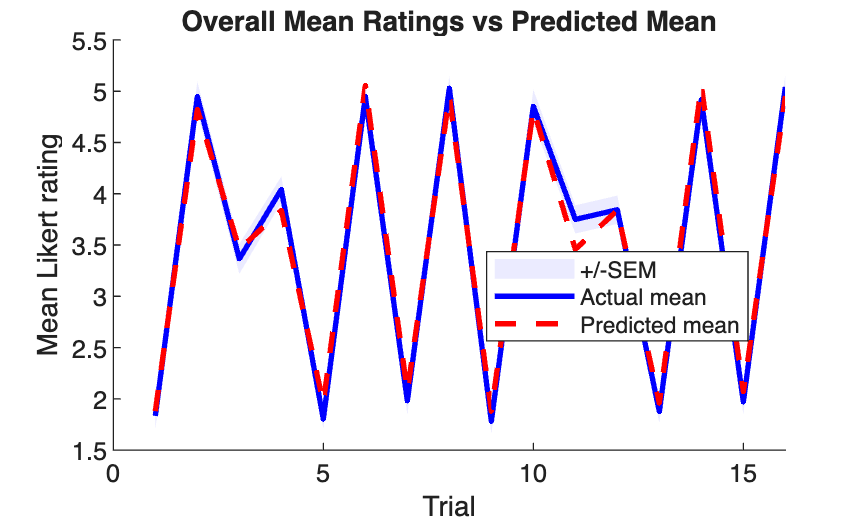

% -------- Generate summary plots --------
projectDir = '/Users/foxxis/Desktop/HBI/exp3';
[~, bestModelPerSubj] = max(resp, [], 2);

figDir = fullfile(projectDir, 'results', 'figures');
if ~exist(figDir, 'dir')
    mkdir(figDir);
end

% 1) Overall mean ratings
plot_overall_means(data, cbm, bestModelPerSubj);

figFile = fullfile(figDir, 'overall_means.fig');
savefig(gcf, figFile);
fprintf('Saved: %s\n', figFile);

Saved: /Users/foxxis/Desktop/HBI/exp3/results/figures/overall_means.fig


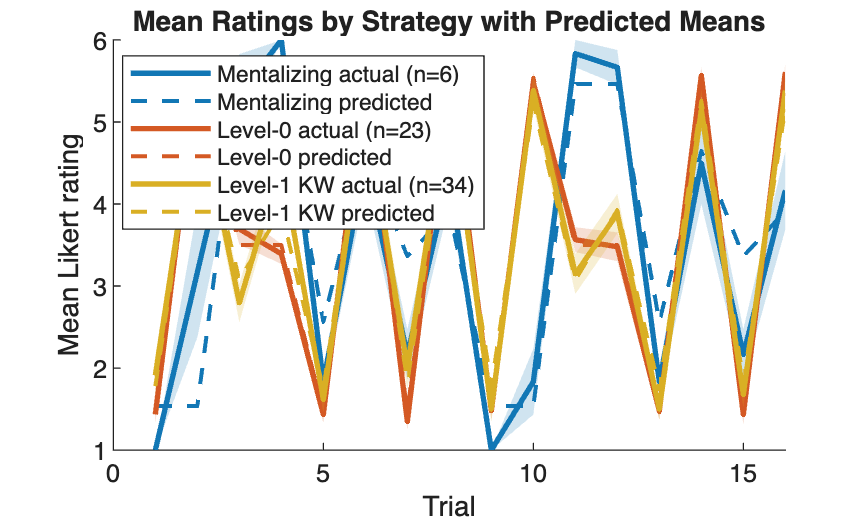

assert(isfile(figFile), 'Figure was not saved.');

% 2) Mean ratings by strategy
plot_choices_by_strategy(data, cbm, bestModelPerSubj);

figFile = fullfile(figDir, 'choices_by_strategy.fig');
savefig(gcf, figFile);
fprintf('Saved: %s\n', figFile);

Saved: /Users/foxxis/Desktop/HBI/exp3/results/figures/choices_by_strategy.fig


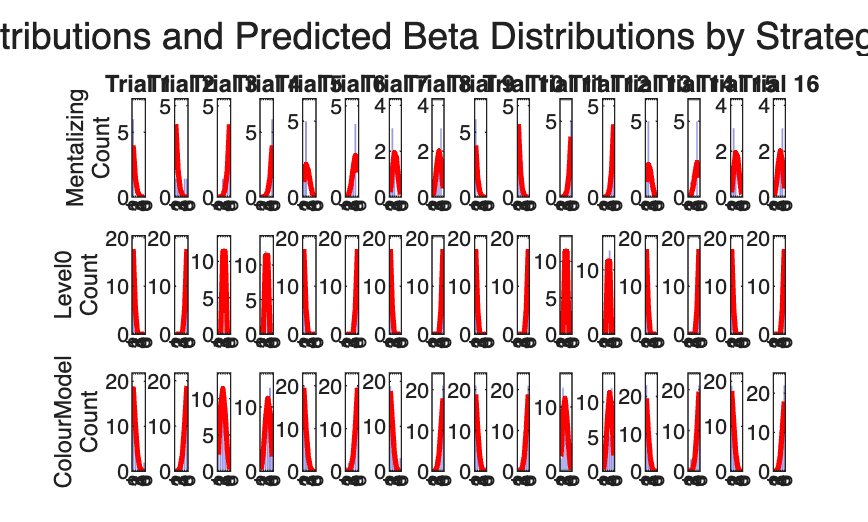

assert(isfile(figFile), 'Figure was not saved.');

% 3) Choice distributions
plot_choice_distribution_beta(data, cbm, bestModelPerSubj);

figFile = fullfile(figDir, 'choice_distribution_beta.fig');
savefig(gcf, figFile);
fprintf('Saved: %s\n', figFile);

Saved: /Users/foxxis/Desktop/HBI/exp3/results/figures/choice_distribution_beta.fig


assert(isfile(figFile), 'Figure was not saved.');

Robustness Check

cd(fullfile(projectDir, 'results', 'fitting'));

v = 5;

% First, we should run cbm_lap, which fits every model to each subject data
% separately (i.e. in a non-hierarchical fashion).
% Mentalizing model: one free parameter (log_ce)
prior_ment = struct('mean', zeros(1,1), 'variance', v);
cbm_lap(data, @mentalizing_model, prior_ment, 'lap_mentalizing_r.mat');

cbm_lap                                           24-Sep-2026 15:17:49
Number of samples: 96
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


% Level-0 model: two free parameters (log_ce, log_n)
prior_vt = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @vt_model, prior_vt, 'lap_vt_r.mat');

cbm_lap                                           24-Sep-2026 15:17:51
Number of samples: 96
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
--- This initialization was aborted (there might be a problem with the model)
--- The message of optimization routine is:
---    W must be real and non-negative.
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject:


% Level-1 (diversity weighted) model: three free parameters (log_ce, log_n, log_e)
prior_dw = struct('mean', zeros(3,1), 'variance', v);
cbm_lap(data, @dw_model, prior_dw, 'lap_dw_r.mat');

cbm_lap                                           24-Sep-2026 15:17:58
Number of samples: 96
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
--- This initialization was aborted (there might be a problem with the model)
--- The message of optimization routine is:
---    W must be real and non-negative.
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
--- This initialization was aborted (there might be a problem with the model)
--- The message of optimization routine is:
---    Z must be real and non-negative.
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Su


% Level-2 (knowledge weighted) model: two free parameters (log_ce, log_n)
prior_kw = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @kw_model, prior_kw, 'lap_kw_r.mat');

cbm_lap                                           24-Sep-2026 15:18:13
Number of samples: 96
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
--- This initialization was aborted (there might be a problem with the model)
--- The message of optimization routine is:
---    Z must be real and non-negative.
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
--- This initialization was aborted (there might be a pr


% Baseline model: zero free parameters (uniform over responses)
prior_base = struct('mean', 0, 'variance', v);
cbm_lap(data, @baseline_model, prior_base, 'lap_baseline_r.mat');

cbm_lap                                           24-Sep-2026 15:18:20
Number of samples: 96
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


% Conduct hierarchical Bayesian inference using cbm_hbi
models = {@mentalizing_model, @vt_model, @dw_model, @kw_model, @baseline_model};
fcbm_maps = {'lap_mentalizing_r.mat', 'lap_vt_r.mat', 'lap_dw_r.mat', 'lap_kw_r.mat', 'lap_baseline_r.mat'};
hbi_file = 'hbi_compare_r.mat';
cbm_hbi(data, models, fcbm_maps, hbi_file);

cbm_hbi_hbi                                       24-Sep-2026 15:18:22
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_mentalizing_r.mat [for model 1]
	lap_vt_r.mat [for model 2]
	lap_dw_r.mat [for model 3]
	lap_kw_r.mat [for model 4]
	lap_baseline_r.mat [for model 5]
 
Number of samples: 96
Number of models: 5
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 10.9| model 2: 30.0| model 3: 26.0| model 4: 26.5| model 5: 6.5| 
                                                           dL:   36.22
                                                           dm:   70.02
                                                           dx:    0.58
Iteration 03
	model frequencies (percent)
	model 1: 10.0| model 2: 31.9| model 3: 24.3| model 4: 28.4| model 5: 5.5| 
                                                           dL:    2.60
                                      


% Load the saved file
S = load(hbi_file);
assert(isfield(S, 'cbm'), 'No cbm variable found in %s.', hbi_file);
cbm = S.cbm;
cbm.output

ans = struct with fields:
                     parameters: {5×1 cell}
                 responsibility: [96×5 double]
                     group_mean: {[1.0822]  [3.3393 0.7831]  [3.1768 0.0496 0.5487]  [1.6748 1.7223]  [2.5993e-09]}
    group_hierarchical_errorbar: {[0.3786]  [0.2689 0.1882]  [0.6094 0.2059 0.2926]  [0.1440 0.2774]  [0.2135]}
                model_frequency: [0.0795 0.3111 0.0988 0.4439 0.0666]
                exceedance_prob: [0 0.0683 0 0.9317 0]
      protected_exceedance_prob: [NaN NaN NaN NaN NaN]


model_frequency = cbm.output.model_frequency

model_frequency =     0.0795    0.3111    0.0988    0.4439    0.0666


group_mean_m = cbm.output.group_mean{1};group_mean_m

group_mean_m = 1.0822

group_mean_mv = cbm.output.group_mean{2};group_mean_mv

group_mean_mv =     3.3393    0.7831


group_mean_dw = cbm.output.group_mean{3};group_mean_dw

group_mean_dw =     3.1768    0.0496    0.5487


group_mean_kw = cbm.output.group_mean{4};group_mean_kw

group_mean_kw =     1.6748    1.7223


group_mean_b = cbm.output.group_mean{5};group_mean_b

group_mean_b = 2.5993e-09

responsibility = cbm.output.exceedance_prob

responsibility =          0    0.0683         0    0.9317         0



% Calculate protected exceedance probabilities by re-running under the (prior) null hypothesis
cbm_hbi_null(data,hbi_file)

cbm_hbi_hbi                                       24-Sep-2026 15:18:47
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_mentalizing_r.mat [for model 1]
	lap_vt_r.mat [for model 2]
	lap_dw_r.mat [for model 3]
	lap_kw_r.mat [for model 4]
	lap_baseline_r.mat [for model 5]
 
Number of samples: 96
Number of models: 5
Iteration 01
Iteration 02
                                                           dL:    8.67
                                                           dx:    0.12
Iteration 03
                                                           dL:    0.46
                                                           dx:    0.02
Iteration 04
                                                           dL:    0.27
                                                           dx:    0.01
Iteration 05
                                                           dL:    0.2

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]



% Load the corrected HBI results
S   = load(hbi_file, 'cbm');
cbm = S.cbm;

% Extract posterior quantities (for inspection)
pxp  = cbm.output.protected_exceedance_prob;
pxp

pxp =     0.0000    0.0683    0.0000    0.9317    0.0000


Local helper functions

function validate_cbm_data(data)
%VALIDATE_CBM_DATA Basic validation for CBM data cell arrays.

assert(iscell(data) && ~isempty(data), ...
    'Data must be a non-empty cell array of subject structs.');

assert(isstruct(data{1}) && isfield(data{1}, 'y'), ...
    'Each data cell must contain a struct with field y.');

M = numel(data{1}.y);
assert(M == 16, 'Experiment 3 expects 16 responses per subject.');

for s = 1:numel(data)
    assert(isstruct(data{s}) && isfield(data{s}, 'y'), ...
        'data{%d} must be a struct with field y.', s);
    assert(numel(data{s}.y) == M, ...
        'Subject %d has %d trials; expected %d.', s, numel(data{s}.y), M);
end
end